## FDM 3 dimenzióban

#### 1. feladat


$$\begin{cases}
-\Delta u=f\quad \textrm{in}\ \Omega = [0,1] \times [0,1] \times [0,1]\\
u\big|_{\Gamma}=0, & \\
f(x,y,z) =  3\pi^2 \sin( \pi x) \sin (\pi y ) \sin (\pi z)
\end{cases}\\
\text{Ennek megoldása:}
\quad u(x,y,z) = \sin( \pi x) \sin (\pi y ) \sin (\pi z)$$


### Megoldás közelítése

A 3 dimenziós FDM-hez tartozó együttható mátrix:

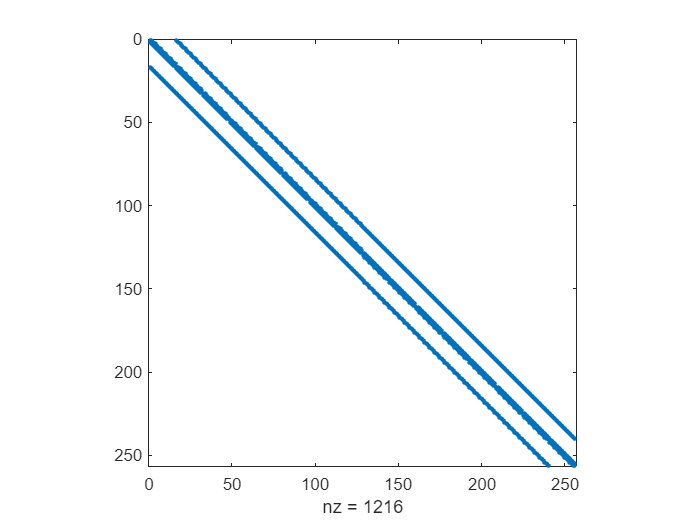

% belso pontok szama
N = 16;

% lepeshossz
h = 1/(N+1);

e = ones(N,1);
E = spdiags([-1*e,6*e,-1*e],[-1,0,1],N,N);
F = -1*speye(N);

Tmp1 = spdiags([e,e],[-1,1],N,N);
B_tilde = kron(speye(N),E) + kron(Tmp1,F);
spy(B_tilde);

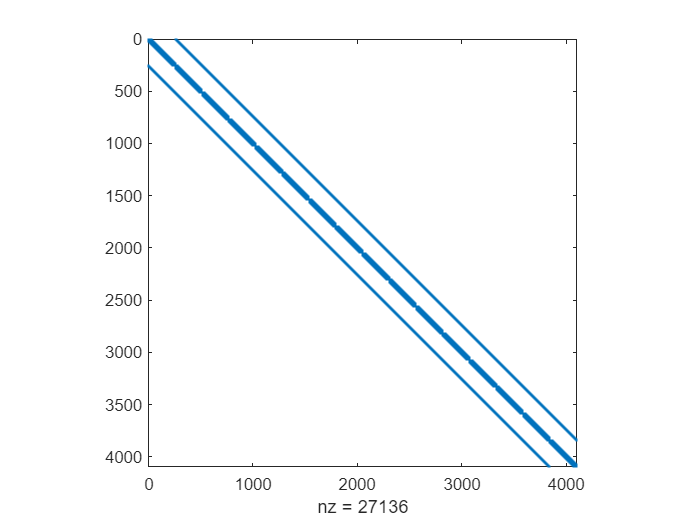

I = speye(N^2);
A_h = 1/h^2 * (kron(speye(N),B_tilde) + kron(Tmp1,(-1)*I));

spy(A_h)

Numerikusan közelített értékek a rácspontokban

% 3d
[xi,yj,zk] = meshgrid(h:h:1-h,h:h:1-h,h:h:1-h);
tmp=3*exp(-10*(xi-0.2).^2-10*(yj-0.2).^2-10*(zk-1).^2)+exp(-10*(xi-0.8).^2-10*(yj-0.7).^2-10*(zk-1).^2);
%tmp=exp(-15*(xi-0).^2-15*(yj-0).^2-15*(zk-1).^2);
f=3*pi^2*reshape(pagetranspose(tmp),N^3,1);

% numerikusan kozelitett ertekek
y = A_h\f;

ybrick=reshape(y,N,N,N);
ybrick = pagetranspose(ybrick);


### Gradiens

A közelített értékekből becsült gradiens értéke a belső rácspontokban:

ybrickfull = zeros(N+2,N+2,N+2); % tartalmazza a hataroldalakat is
ybrickfull(2:N+1,2:N+1,2:N+1) = ybrick;

grad_firstcoord = zeros(N+2,N+2,N+2);
grad_secondcoord = zeros(N+2,N+2,N+2);
grad_thirdcoord = zeros(N+2,N+2,N+2);


% belso pontokban szimmetrikus semaval kozelitjuk a derivaltat
grad_firstcoord(2:N+1,:,:) = (ybrickfull(3:N+2,:,:)-ybrickfull(1:N,:,:))/(2*h);
grad_secondcoord(:,2:N+1,:) = (ybrickfull(:,3:N+2,:)-ybrickfull(:,1:N,:))/(2*h);
grad_thirdcoord(:,:,2:N+1) = (ybrickfull(:,:,3:N+2)-ybrickfull(:,:,1:N))/(2*h);


Közelített gradiens abszolút értéke a belső pontokban:

abs_num_grad = zeros(N+2,N+2,N+2);
for i = [1,N+2]
    for j = [1,N+2]
        for k = [1,N+2]
            abs_num_grad(i,j,k) = norm([grad_firstcoord(i,j,k),grad_secondcoord(i,j,k),grad_thirdcoord(i,j,k)]);
        end
    end
end


Közelített gradiens abszolút értéke a tégla határán:

% oldalakban
abs_num_grad(1,:,:)=(ybrickfull(2,:,:)-ybrickfull(1,:,:))/h;
abs_num_grad(N+2,:,:)=(ybrickfull(N+2,:,:)-ybrickfull(N+1,:,:))/h;
abs_num_grad(:,1,:)=(ybrickfull(:,2,:)-ybrickfull(:,1,:))/h;
abs_num_grad(:,N+2,:)=(ybrickfull(:,N+2,:)-ybrickfull(:,N+1,:))/h;
abs_num_grad(:,:,1)=(ybrickfull(:,:,2)-ybrickfull(:,:,1))/h;
abs_num_grad(:,:,N+2)=(ybrickfull(:,:,N+2)-ybrickfull(:,:,N+1))/h;

% eleken
% fuggoleges elek (z)
abs_num_grad(1,1,:)=(ybrickfull(2,2,:)-ybrickfull(1,1,:))/(sqrt(2)*h);
abs_num_grad(1,N+2,:)=(ybrickfull(2,N+1,:)-ybrickfull(1,N+2,:))/(sqrt(2)*h);

abs_num_grad(N+2,1,:)=(ybrickfull(N+1,2,:)-ybrickfull(N+2,1,:))/(sqrt(2)*h);
abs_num_grad(N+2,N+2,:)=(ybrickfull(N+1,N+1,:)-ybrickfull(N+2,N+2,:))/(sqrt(2)*h);

%vizszintes elek (y)
abs_num_grad(1,:,1)=(ybrickfull(2,:,2)-ybrickfull(1,:,1))/(sqrt(2)*h);
abs_num_grad(N+2,:,1)=(ybrickfull(N+1,:,2)-ybrickfull(N+2,:,1))/(sqrt(2)*h);

abs_num_grad(1,:,N+2)=(ybrickfull(2,:,N+1)-ybrickfull(1,:,N+2))/(sqrt(2)*h);
abs_num_grad(N+2,:,N+2)=(ybrickfull(N+1,:,N+1)-ybrickfull(N+2,:,N+2))/(sqrt(2)*h);

%vizszintes elek (x)
abs_num_grad(:,1,1)=(ybrickfull(:,2,2)-ybrickfull(:,1,1))/(sqrt(2)*h);
abs_num_grad(:,N+2,1)=(ybrickfull(:,N+1,2)-ybrickfull(:,N+2,1))/(sqrt(2)*h);

abs_num_grad(:,1,N+2)=(ybrickfull(:,2,N+1)-ybrickfull(:,1,N+2))/(sqrt(2)*h);
abs_num_grad(:,N+2,N+2)=(ybrickfull(:,N+1,N+1)-ybrickfull(:,N+2,N+2))/(sqrt(2)*h);

% sarkokban 
abs_num_grad(1,1,1) = (ybrickfull(2,2,2)-ybrickfull(1,1,1))/(sqrt(3)*h);
abs_num_grad(N+2,1,1) = (ybrickfull(N+1,2,2)-ybrickfull(N+2,1,1))/(sqrt(3)*h);
abs_num_grad(1,N+2,1) = (ybrickfull(2,N+1,2)-ybrickfull(1,N+2,1))/(sqrt(3)*h);
abs_num_grad(N+2,N+2,1) = (ybrickfull(N+1,N+1,2)-ybrickfull(N+2,N+2,1))/(sqrt(3)*h);

abs_num_grad(1,1,N+2) = (ybrickfull(2,2,N+1)-ybrickfull(1,1,N+2))/(sqrt(3)*h);
abs_num_grad(N+2,1,N+2) = (ybrickfull(N+1,2,N+1)-ybrickfull(N+2,1,N+2))/(sqrt(3)*h);
abs_num_grad(1,N+2,N+2) = (ybrickfull(2,N+1,N+1)-ybrickfull(1,N+2,N+2))/(sqrt(3)*h);
abs_num_grad(N+2,N+2,N+2) = (ybrickfull(N+1,N+1,N+1)-ybrickfull(N+2,N+2,N+2))/(sqrt(3)*h);

% most vesszük az összes pontban az abszolút értéket:
abs_num_grad = abs(abs_num_grad);


A becsült gradiens vizualizációja a tégla határán hőtérképpel:

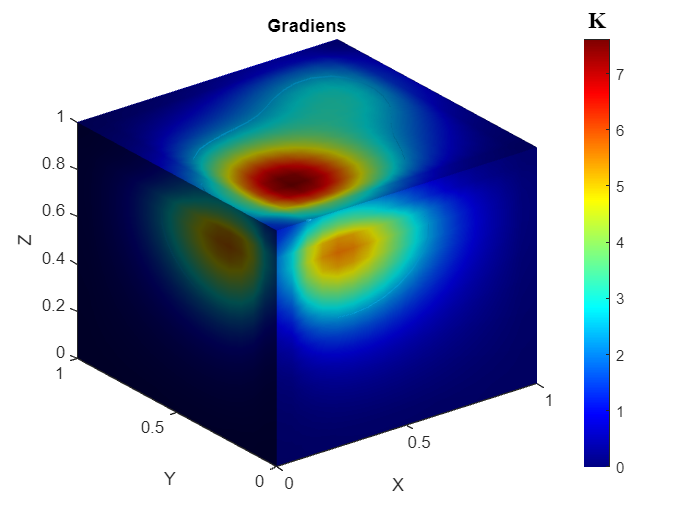

x=0:h:1;
y=x;
z=y;
[xx, yy, zz] = meshgrid(x,y,z);  %=meshgrid(0:h:1, 0:h:1, 0:h:1);

fc = abs_num_grad;

fmax=max(max(max(fc)));   
fmin=min(min(min(fc))); 
clf
isosurface(xx, yy, zz, fc)
colorbar
colormap jet
[fe, ve, ce] = isocaps(x, y, z, fc, -10);
p2 = patch('Faces', fe, 'Vertices', ve, 'FaceVertexCData', ce);
p2.FaceColor = 'interp';
p2.EdgeColor = 'none' ;
grid on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Gradiens');
%set(gca, 'clim', [-1.7  0])       %this gives a colormap on a fixed range
set(gca, 'clim', [fmin  fmax])     %this makes the colormap fill the range of the studied function 
set(get(colorbar, 'title'), 'string', 'K', 'FontW', 'bold', 'fontname', 'Times New Roman', 'fontsize', 14);
view(3)